# Satellite Control with Fuzzy PI Controller

#### 1) Classic PI Controller

We assume the following closed loop system that controls the orientation angle $y$ of a satellite through the controller $G_{c\;} \left(s\right)=K_p \frac{\left(s+c\right)}{s}$, where $c=\frac{K_I }{K_p }$: 

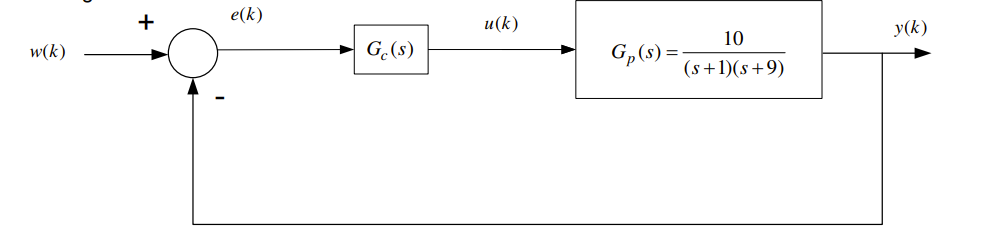

We need to tune the parameters of the controller to achieve overshoot < 10% for step input and rise time < 1.2 seconds. We set these requirements in Control System Designer and we select $K_p =1$ and $c=1\ldotp 5$.

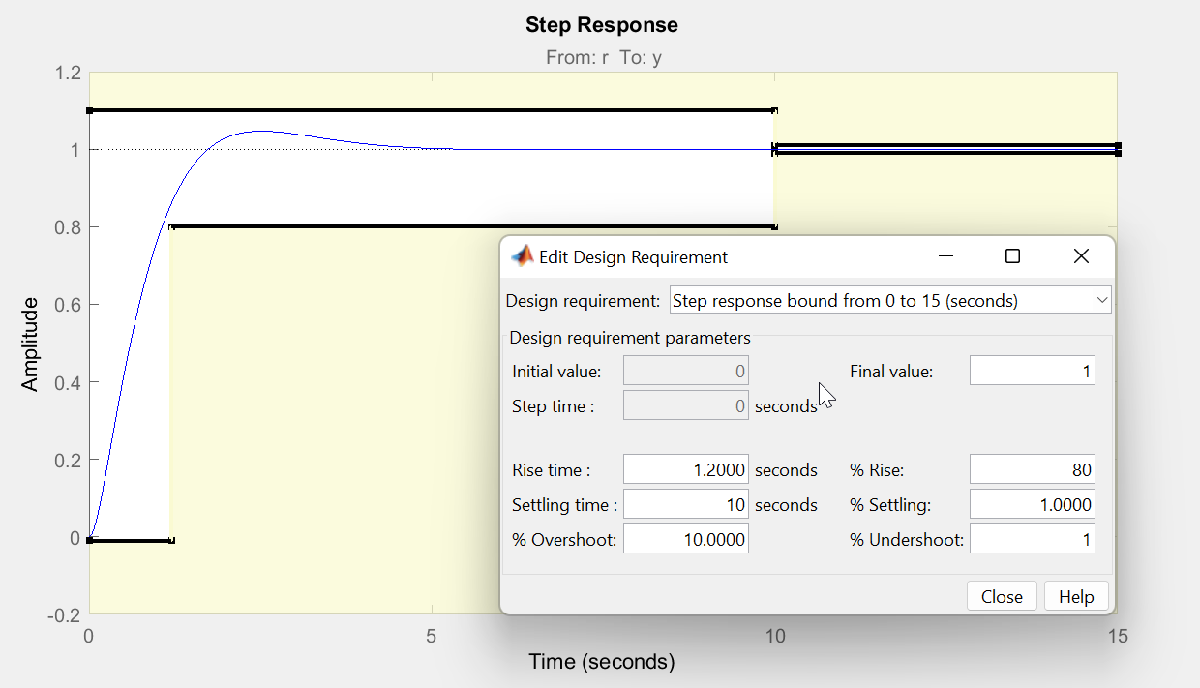

clc;
clear;

Kp = 1;
Ki = 1.5;
Gc = zpk(-Ki / Kp, 0, Kp);
Gp = zpk([], [-1 -9], 10);

openLoop = Gc * Gp;
sys = feedback(openLoop, 1, -1)


sys =
 
            10 (s+1.5)
  -------------------------------
  (s+7.814) (s^2 + 2.186s + 1.92)
 
Continuous-time zero/pole/gain model.



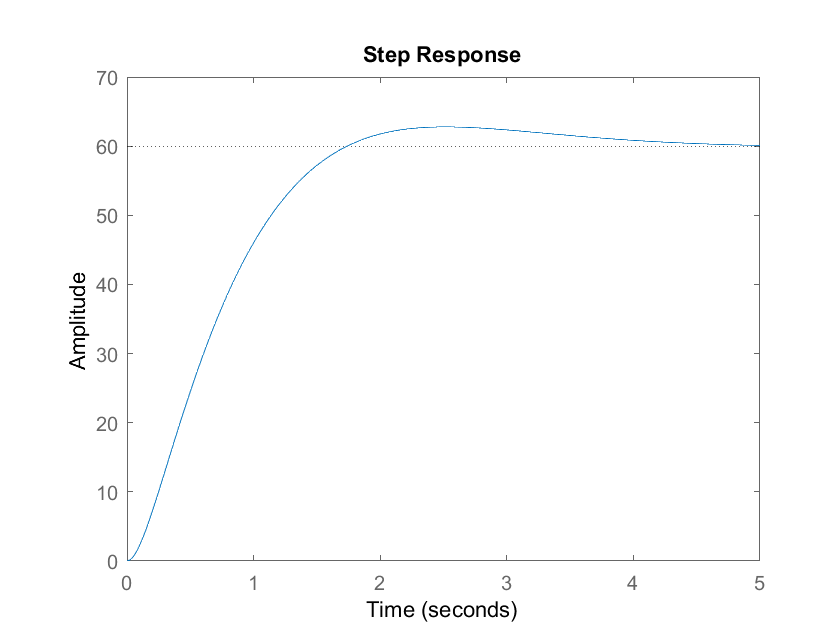


opt = stepDataOptions;
opt.StepAmplitude = 60;

figure()
step(sys,opt)

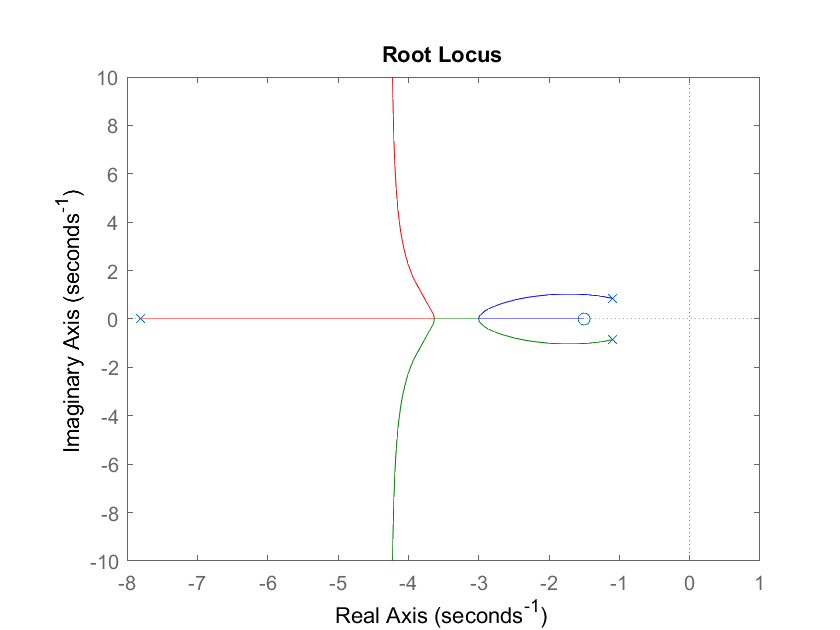

figure()
rlocus(sys)

stepinfo(sys)

ans = struct with fields:
        RiseTime: 1.13430959331694
    SettlingTime: 3.72489243934137
     SettlingMin: 0.902579271500868
     SettlingMax: 1.04638896561874
       Overshoot: 4.63889656187384
      Undershoot: 0
            Peak: 1.04638896561874
        PeakTime: 2.5105685222914

#### 2) Fuzzy PI Controller

Now, we create a PI Fuzzy Logic Controller. We consider as inputs the tracking error $e$ and its time derivative $\dot{e}$, while the output is the derivative of the control singal $\dot{u}$. 

The membership function for the inputs is defined by the following figure:

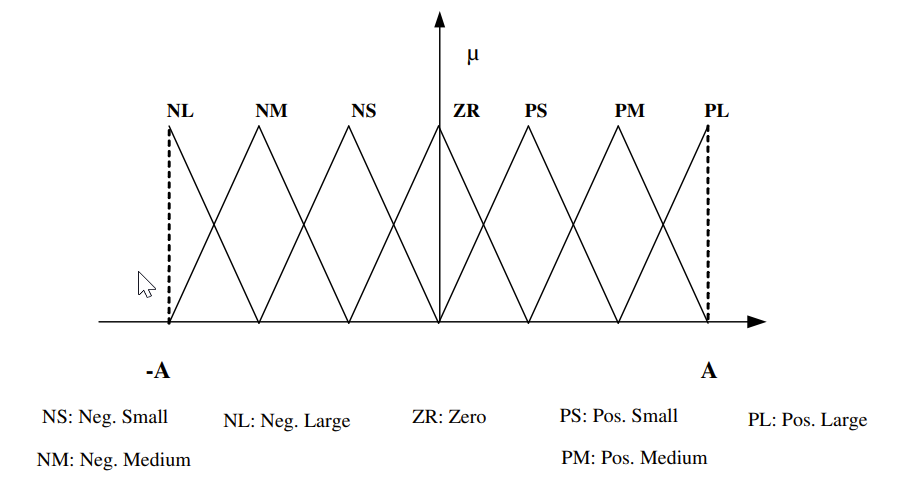

while the membership function of the output is the following: 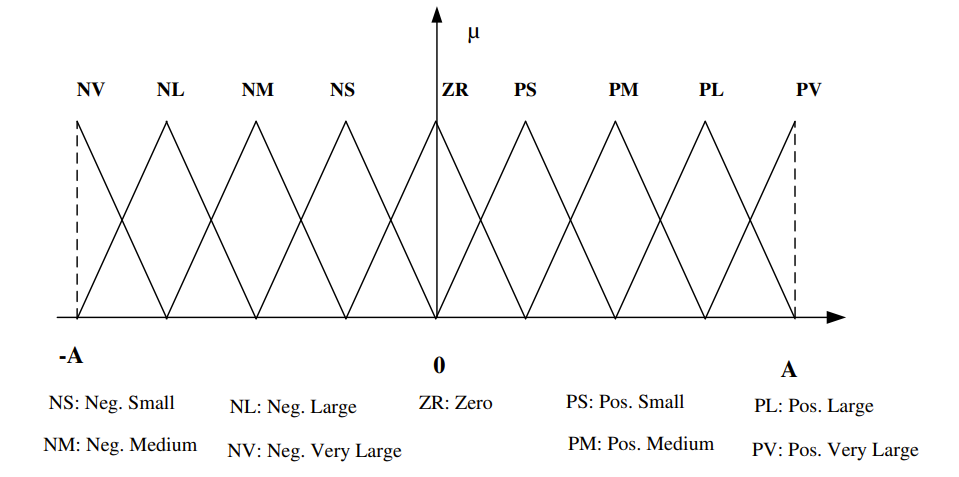

FLC = readfis('FLC')

FLC =   mamfis with properties:

                       Name: "FLC"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "prod"
          AggregationMethod: "max"
      DefuzzificationMethod: "CenterOfSums"
                     Inputs: [1×2 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×49 fisrule]
    DisableStructuralChecks: 0
	See 'getTunableSettings' method for parameter optimization.

The rules of the controller are defined from the following table, which shows the outputs for all the combinations of inputs:

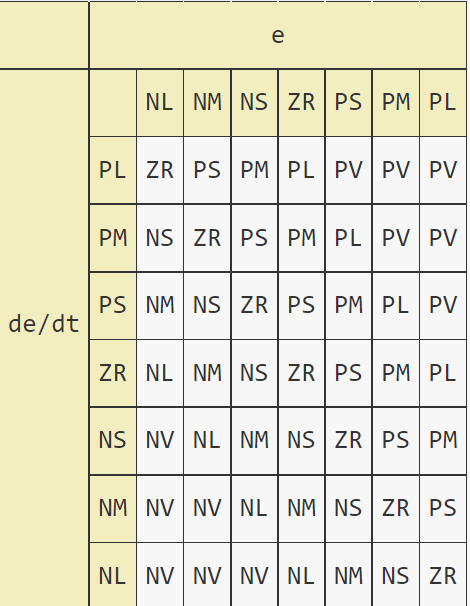

We create the following system on Simulink:

FLCSim

We normalize and denormalize the reference and output signals respectively, taking under consideration that they are in $\left\lbrack 0,60\right\rbrack$. Also,we use saturation function to fix the inputs of the FLC between -1 and 1 values.

We also tuned the gains of the system to achieve better results than the previous PI controller.

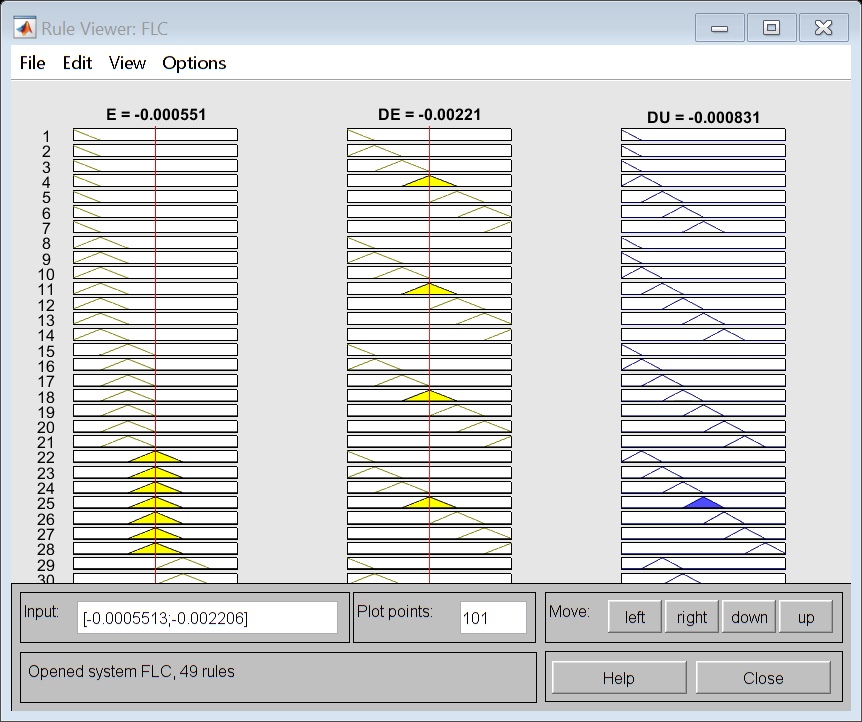

sim('FLCSim')

### a) System respone

In the next figure, the step responses of the two separate controllers alongside the reference are presented.

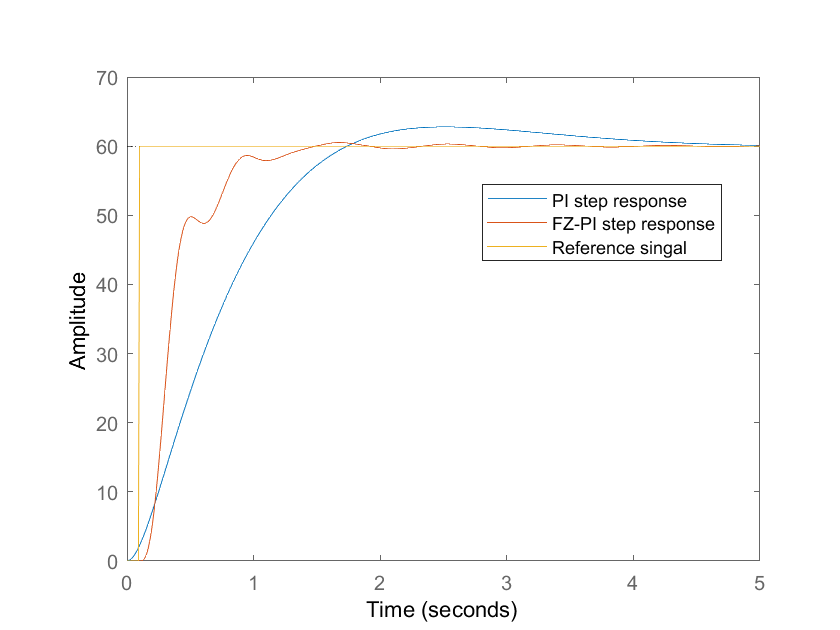

figure()
hold on;
step(sys,opt);
plot(simout.time, simout.signals.values(:, 1), 'color', [0.8500, 0.3250, 0.0980]);
plot(simout.time, simout.signals.values(:, 2), 'color', [0.9290, 0.6940, 0.1250]);
title('');
legend('PI step response', 'FZ-PI step response', 'Reference singal', 'Location', "best");
hold off;

We can validate that the Fuzzy PI Controller performs better in terms of overshoot and rise time:

stepinfo(simout.signals.values(:, 1), simout.time)

ans = struct with fields:
        RiseTime: 0.565326689167668
    SettlingTime: 1.27022998509672
     SettlingMin: 54.466374456069
     SettlingMax: 60.5214889842389
       Overshoot: 0.813574809479944
      Undershoot: 0
            Peak: 60.5214889842389
        PeakTime: 1.67

### b) Base functionality

We assume the FLC inputs $e=\mathrm{PS}$ and $\dot{e} =\mathrm{NM}$.

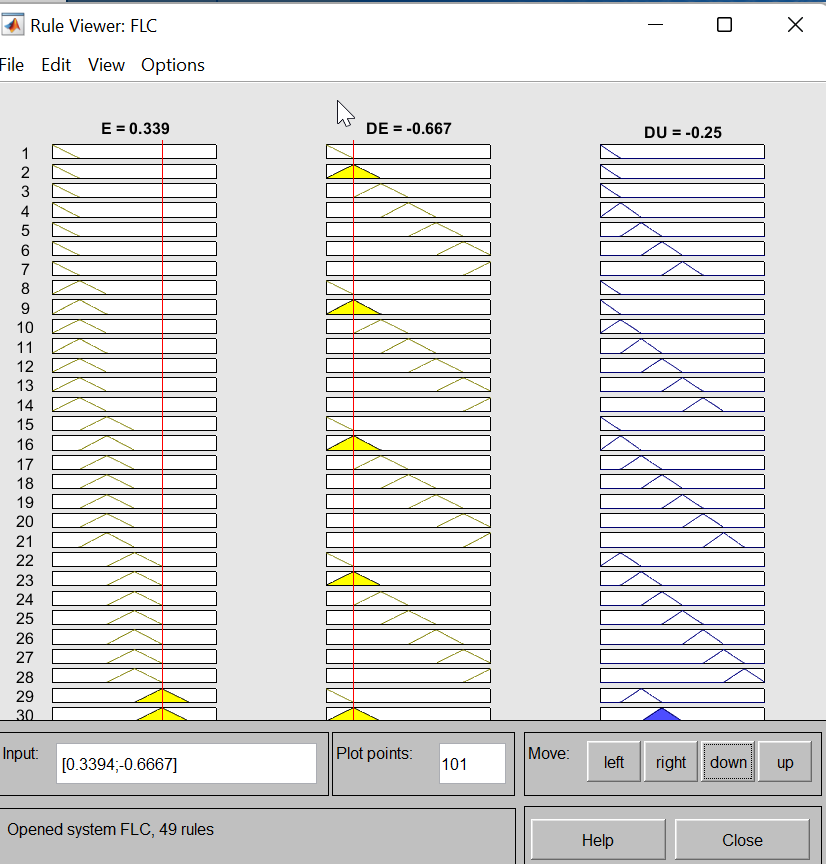

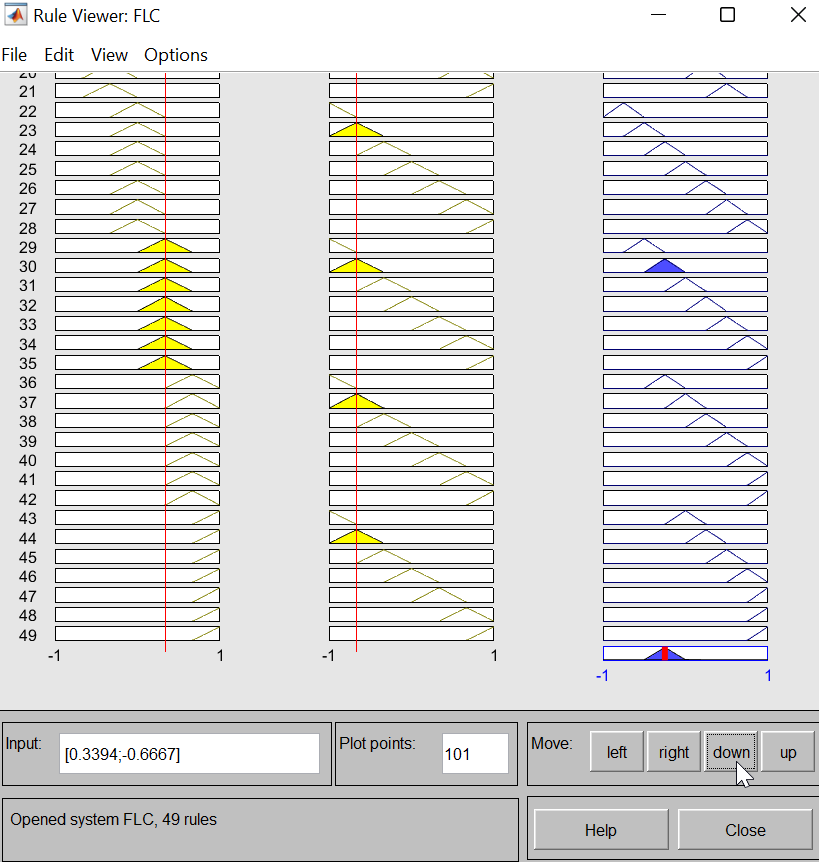

As we see above, rule 30 is activated and the output is $\dot{u} =\mathrm{NS}$.

### c) 3D output surface

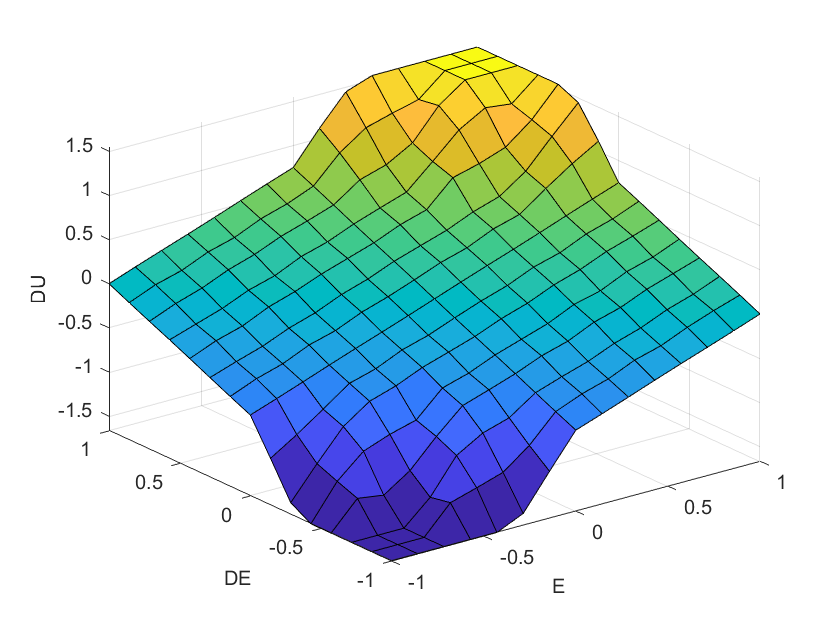

figure()
gensurf(FLC)

### d) Custom input signals

Now we test the ability of the controller to track custom inputs signals. The results of the simulations are presented below. The tracking is very accurate, with low overshoots and high rise times. There are some little oscillations too.

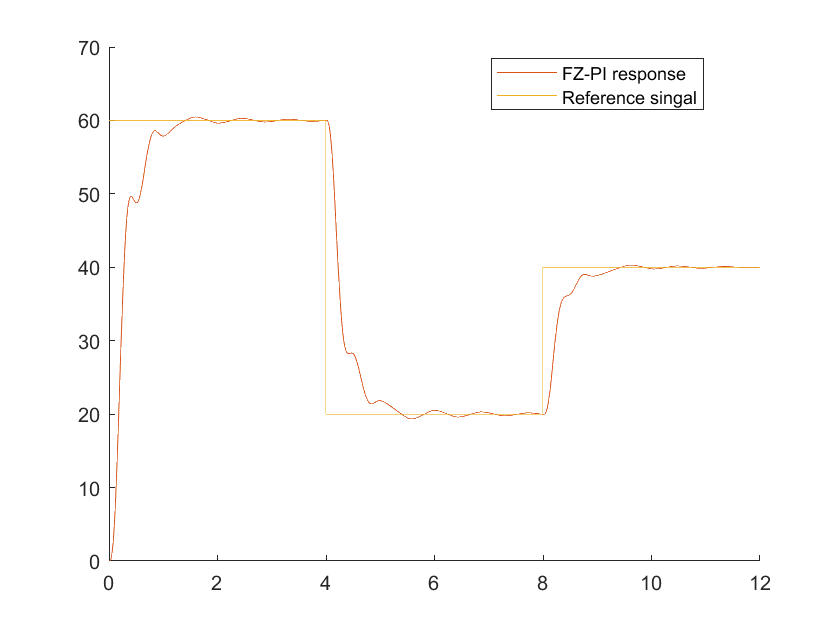

sim('FLCSim2')

figure()
hold on;
plot(simout.time, simout.signals.values(:, 1), 'color', [0.8500, 0.3250, 0.0980]);
plot(simout.time, simout.signals.values(:, 2), 'color', [0.9290, 0.6940, 0.1250]);
legend('FZ-PI response', 'Reference singal', 'Location', "best");
hold off;

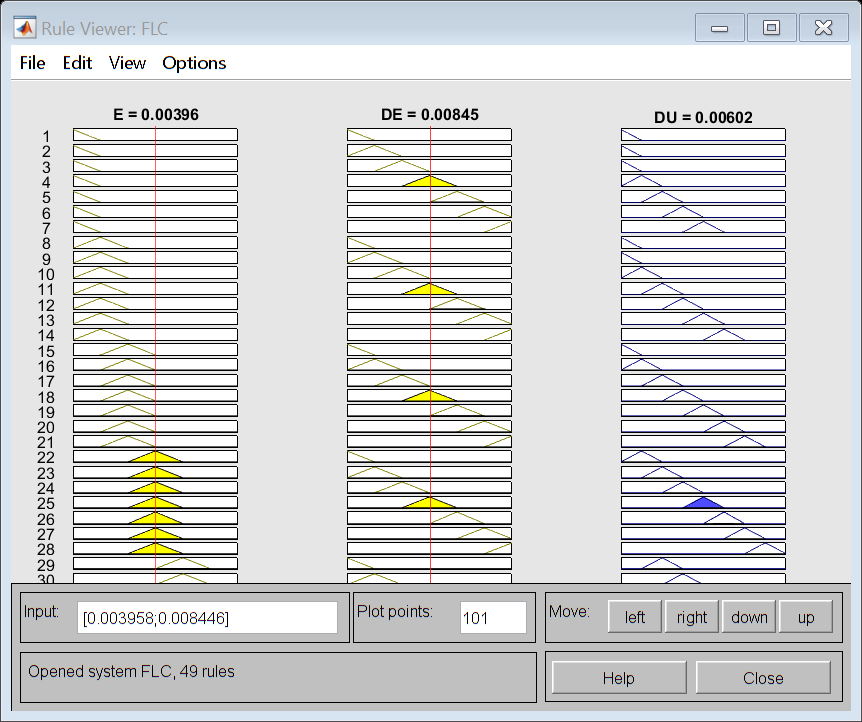

sim('FLCSim3')

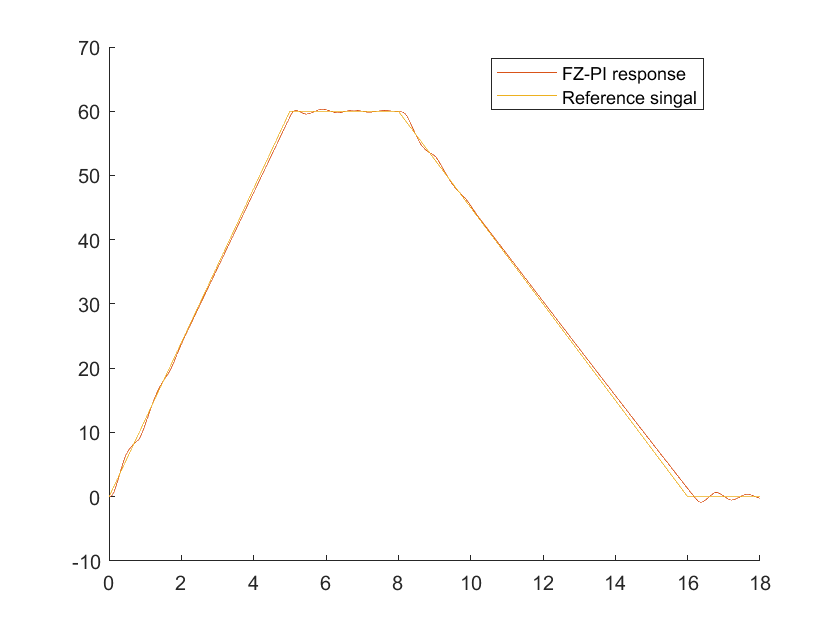

figure()
hold on;
plot(simout.time, simout.signals.values(:, 1), 'color', [0.8500, 0.3250, 0.0980]);
plot(simout.time, simout.signals.values(:, 2), 'color', [0.9290, 0.6940, 0.1250]);
legend('FZ-PI response', 'Reference singal', 'Location', "best");
hold off;